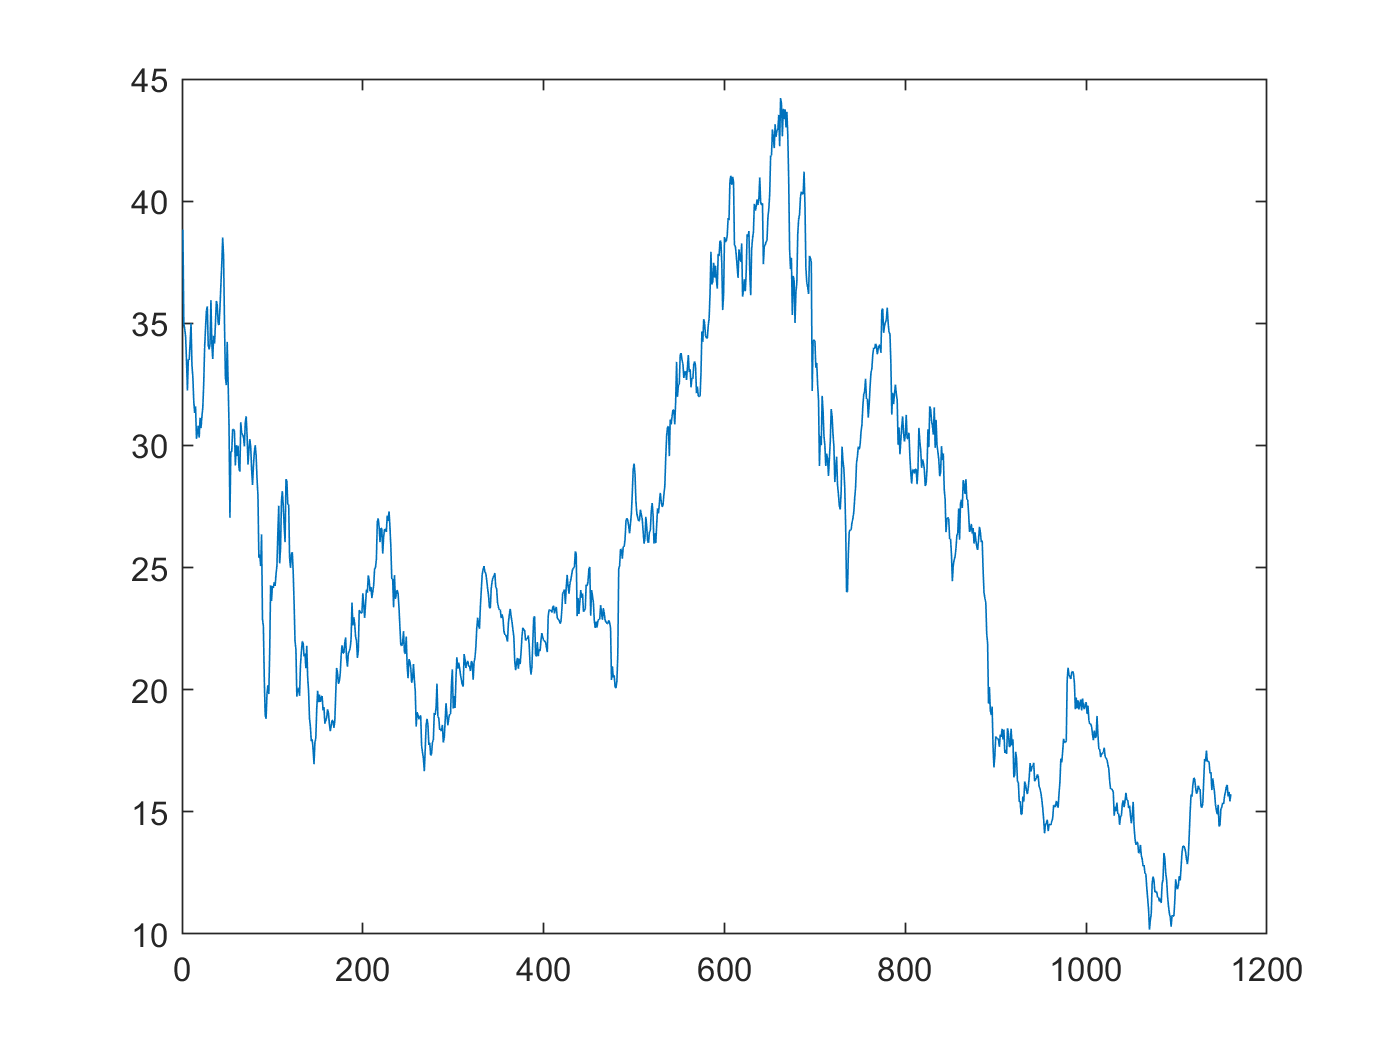

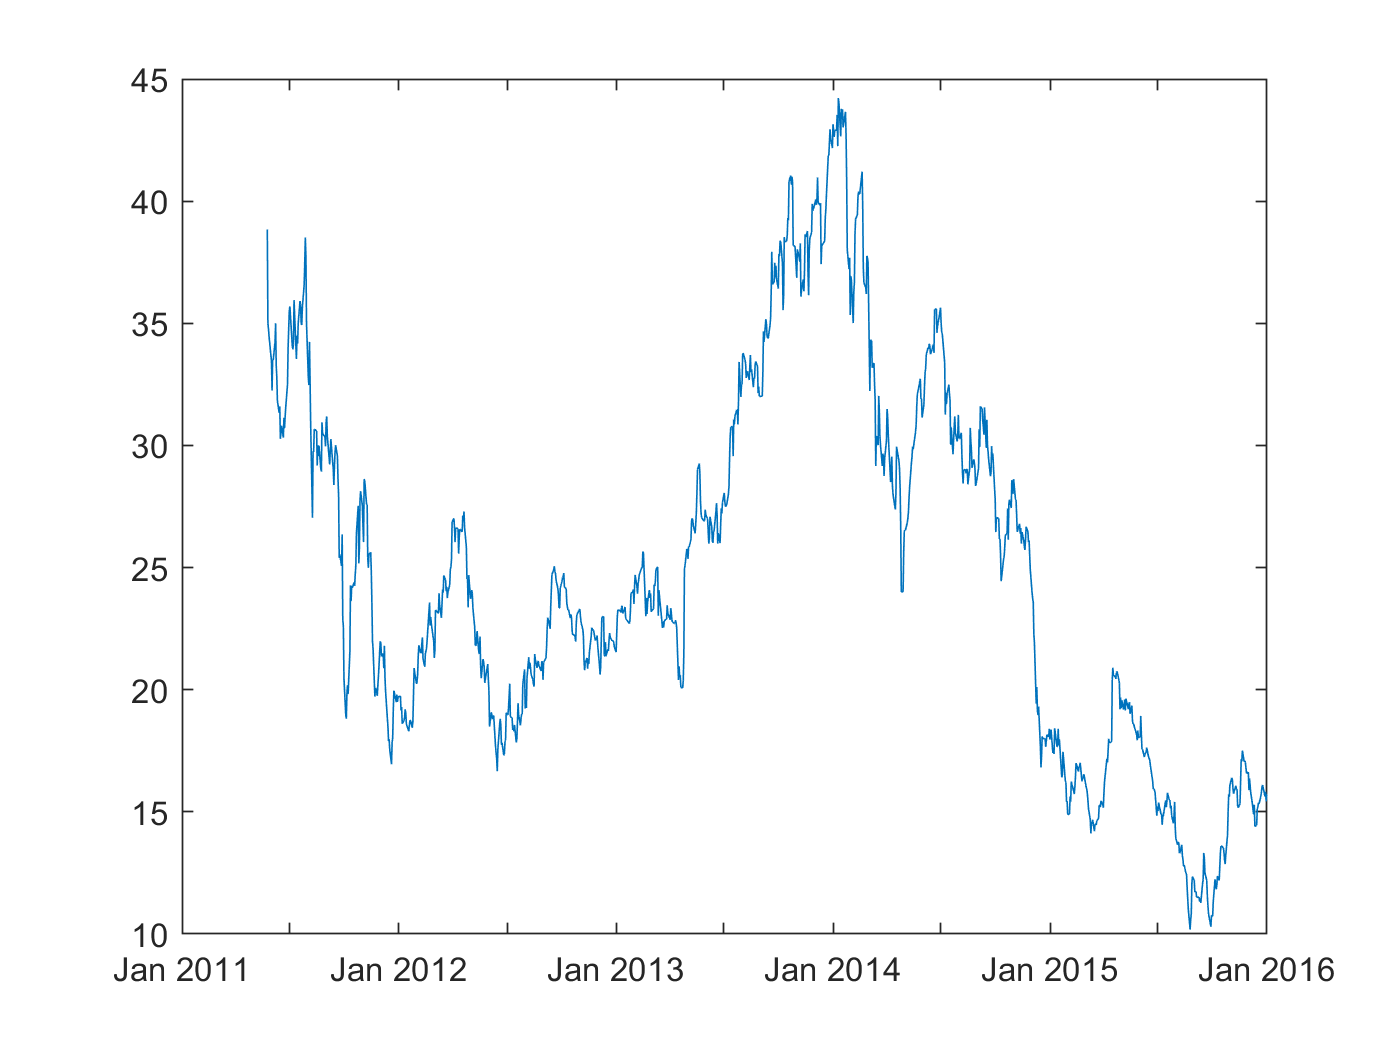

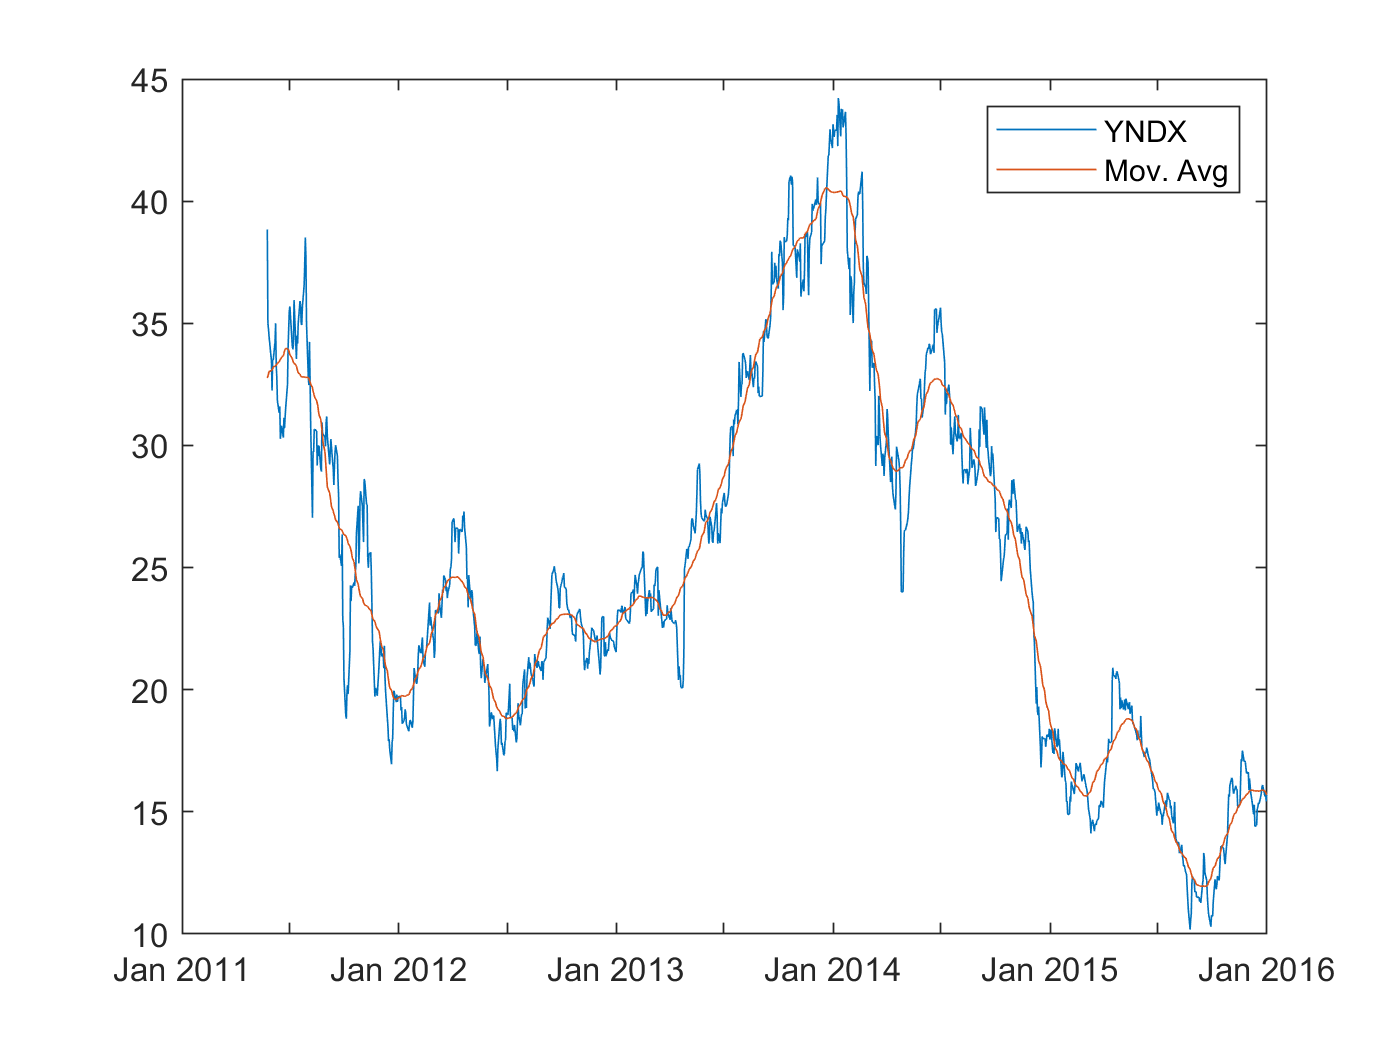

Previously accessible file "D:\MATLAB\Functions\tick2ret.m" is now inaccessible.

stock = get_yahoo_stockdata3('YNDX','01-Jan-2006', '01-Jan-2016');


% array with Adjusted closing price
adjClosePrice = stock.adjClosePrice;

% get dates for stock; already in correct order
dates = stock.DateTime;
actDates = datetime(dates, 'convertfrom', 'datenum');

% plot adjusted price --> x-axis is number and y-axis is price
plot(adjClosePrice);

% plot adjusted price with correct dates
plot(actDates, adjClosePrice);

% calculate moving average for every 50 ticks, array has dimension of 1
movAvg = movmean(adjClosePrice, 50, 1);

% plot moving average on time
plot(actDates, adjClosePrice, actDates, movAvg);
legend('YNDX', 'Mov. Avg');

% figuring out returns on stock
% log return or continuous returns

returns = tick2ret(adjClosePrice, actDates, 'continuous');
figure
histogram(returns, 50);
